# Exercise 2 - DCT Compression

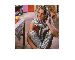

storedStruct = load("D:\digitalImageProc\dgp-2022\Exercises\Ex2\barbara.mat");
barbara = storedStruct.barbara;

imshow(barbara,[]);

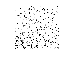



I = im2gray(barbara);

i = dct2(I);
i2 = my2D_DCT(I);
windowSize = [32 32];

dct = @(block_struct) my2D_DCT(block_struct.data);
transformed = blockproc(I,windowSize,dct);



imshow(log(abs(i)));

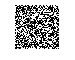

imshow(transformed);

## Quantization - Zone Method

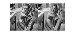

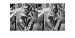

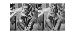

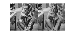

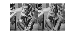

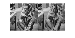

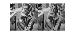

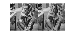

% Keeping only the top right coefficients by applying a mask to each block

MSE = zeros(0.5/0.05,1);

for r=0.05:0.05:0.5
   no_of_coeffs = round(windowSize(1).^2 * r ) ;
    %Creating the mask by keeping upper diagonal matrix with no_of_coeffs
    %elements
    no_of_elements = 1;
    mask = triu(ones(windowSize),no_of_elements);
    while(no_of_coeffs < nnz(mask))
        mask = triu(ones(windowSize),no_of_elements);
        no_of_elements = no_of_elements + 1;

    end

    final_mask = flip(mask,2);
    discarded = blockproc(transformed,windowSize,@(block_struct) (final_mask.*block_struct.data)); %Apply Mask
    
    IDCT = @(block_struct) my2D_IDCT(block_struct.data); %Inverse DCT
    inversedBlocks = blockproc(discarded,windowSize,IDCT); %Apply inverse DCT to every 32x32 block
    
    figure
    imshowpair(I,inversedBlocks,'montage')
    title(sprintf('%d %%',uint8(r*100)))
    
    diff = (double(I)-double(inversedBlocks)).^2;
    min_sq_err = sum(sum(diff))/(256*256); %Minimum Square Error




end